# Clear

clear;
close all; % clear any variable to prevent conflicts

# Defining constant

f = zeros(1,1,2); % initializing the size for frequency(f)
beta = zeros(1,1,2); % initializing the size for beta
c = 3e8; % Speed of light in m/s
for n=1:2 % creating two pages for two frequencies respectively, pg 1 for 2.4GHz while pg2 for 24GHz
    f(:,:,n) = 2.4e8 * 10^(n);
    beta(:,:,n) = 2 * pi .* f(:,:,n) ./ c;
end
Er = sqrt(3/1); % Ratio of dielectric constants between walls(3) and air(1)
tx0 = 0; ty0 = 4; tz0 = 2; % emitting point [x, y, z] location
% point P to Q
rx = 10; ry = 3; rz = 2; % rx [x,y,z] location
rxv = rx:.01:22; % from p to q with .01 increament

# Calculating reflection wall

## Initializing the wall used

twx = 0; twy = 6; twz = 2; % tw (top wall coordinate)[x,y,z] location
bwx = 0; bwy = 0; bwz = 2; % bw (bottom wall coordinate)[x,y,z] location
nor = 4; % number of order of reflection which is 4
txr = twx; tyr = zeros(1,(nor+1)); tzr = 2; % reflection point, which x and z-axes remains the same while y-axis is different
tyru(1,1) = ty0; % first 'reflection point'(emitting point) is ty0 y-axis location, upper wall reflection first
tyrb(1,1)=ty0; % first 'reflection point'(emitting point) is ty0 y-axis location, below wall reflection first

## Calculating reflection point

### Reflection on both walls

for i = 2 : 1: nor+1 % starting from 2 as 1 is the emitting point, nor+1 is 5 as starting point for matlab is 1
    pon = mod(i-1,2); pont = not(pon); % check reflective point on positive or negative side
    tyru(1,i) = tyru(i-1)+2*(twy-tyru(i-1))*pon+2*(bwy-tyru(i-1))*pont; % calculating the reflective point on upper wall first
    tyrb(1,i) = tyrb(i-1)+2*(twy-tyrb(i-1))*pont+2*(bwy-tyrb(i-1))*pon; % calculating the reflective point on lower wall first  
end

## Calculating distances and angle

hypou = zeros(1, length(rxv)); % Initializing hypou
thetau = zeros(1, length(rxv)); % Initializing thetau
thetaur = zeros(1, length(rxv)); % Initializing thetaur
hypob = zeros(1, length(rxv)); % Initializing hypob
thetab = zeros(1, length(rxv)); % Initializing thetab
thetabr = zeros(1, length(rxv)); % Initializing thetabr
for n = 1: nor
    % Upper wall first
    hypou(n,:) = sqrt((ry-(tyru(n+1))).^2+((rxv-tx0)).^2); % hypotheneus(distance between reflection point and rxv) on upper wall first
    thetau(n,:) = asin(rxv./hypou(n, :)); % angle of incidence on upper wall first
    thetaur(n,:) = asin(sin(thetau(n,:))./ Er); % angle of refraction on upper wall first
    % Lower wall first
    hypob(n,:) = sqrt((ry-(tyrb(n+1))).^2+((rxv-tx0)).^2); % hypotheneus(distance between reflection point and rxv) on bottom wall first
    thetab(n,:) = asin(rxv./hypob(n, :)); % angle of incidence on lower wall first
    thetabr(n,:) = asin(sin(thetab(n,:))./ Er); % angle of refraction on lower wall first
end

# Calculating reflection coefficient and electric field strength

## Reflection coefficient

recu = zeros(1, length(rxv)); % Initializing recu(reflection coefficient for upper wall first)
recb = zeros(1, length(rxv)); % Initializing recb(reflection coefficient for bottom wall first)
for n = 1: nor % iterate for 4 times
    recu(n,:) = (cos(thetau(n,:)) - Er.*(cos(thetaur(n,:)))) ./ (cos(thetau(n,:)) + Er.*(cos(thetaur(n,:)))); % calculating recu
    recb(n,:) = (cos(thetab(n,:)) - Er.*(cos(thetabr(n,:)))) ./ (cos(thetab(n,:)) + Er.*(cos(thetabr(n,:)))); % calculating recb
end

## Electric field strength

### Line of sight

los = zeros(1, length(rxv)); % Initializing los
LOS = zeros(1, length(rxv)); % Initializing LOS
d = sqrt(((rxv-tx0).^2)+((ry-ty0)^2)+((rz-tz0)^2)); % finding the distance between emitting point to rxv
for n = 1 : 2 % iterate twice as there are two frequencies, 2.4 and 24GHz respectively
    los(1,:,n) = ((1./d(1,:,:)).*exp(-1j*beta(1,1,n).*d(1,:,:))); % calculating line of sight
    LOS(1,:,n) = 20*log10((los(1,:,n))); % convert to db
end

### Electric field

#### Creating efdu for both frequencies

efdu = zeros(1, length(rxv)); % Initializing efdu
efdb = zeros(1, length(rxv)); % Initializing efdb
efdt = zeros(1, length(rxv)); % Initializing efdt
Efdt= zeros(1, length(rxv)); % Initializing Efdt
for i =1: 2 % iterate twice as there are two frequencies
    for n = 1: nor
        efdu(n,:,i) = (recu(n,:,:).^n).* (1./hypou(n,:,:)) .* exp(-1j* beta(:,:,i) .* hypou(n,:,:)); % calculating electric field for upper wall first
        efdb(n,:,i) = (recb(n,:,:).^n).* (1./hypob(n,:,:)) .* exp(-1j* beta(:,:,i) .* hypob(n,:,:)); % calculating electric field for lower wall first
        % Total electric field
        if n==1
            efdt(n,:,i) = efdu(n,:,i) + efdb(n,:,i); % for the first reflection, can't add any electric field strength
        else
            efdt(n,:,i) = efdt(n-1,:,i) + efdu(n,:,i) + efdb(n,:,i); % onwards, the electric field strength can be added
        end
        Efdt(n,:,i) = 20 .* log10(abs(efdt(n,:,i)+los(:,:,i))); % changing unit to db
    end
end

# Graph

## Graph for 2.4GHz

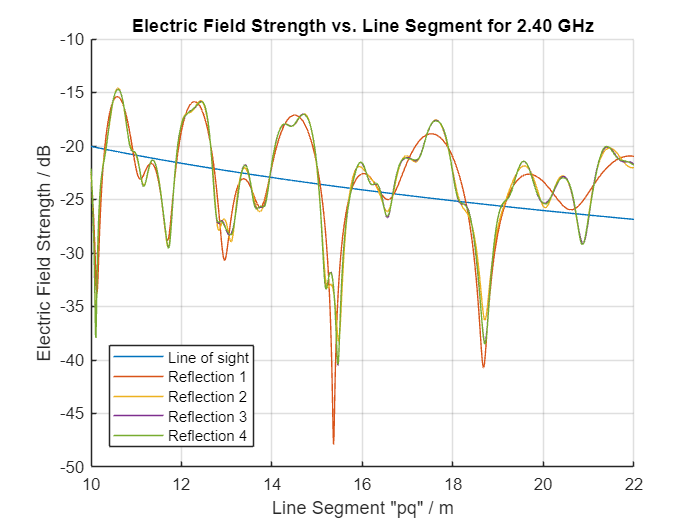

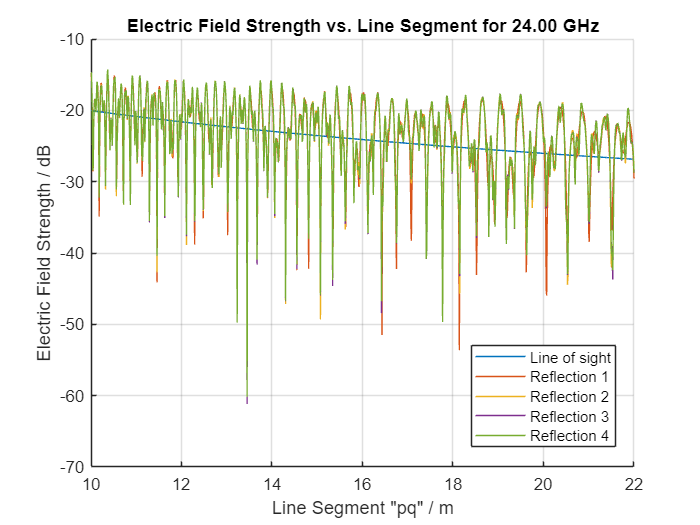

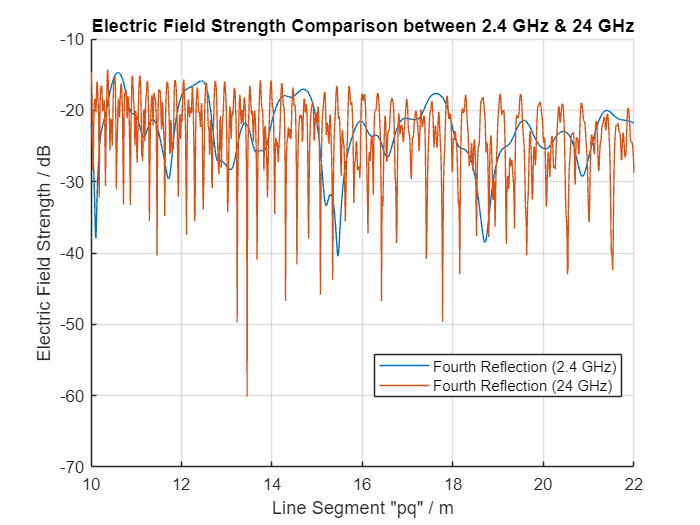

% Plotting the graph for each frequency and the difference graph (three figures)
for i = 1:3
    figure;
    hold on;
    if i == 1 || i == 2
        % Plotting electric field strength vs. line segment for each frequency
        plot(rxv, LOS(1,:,i), 'DisplayName', sprintf('Line of sight')); % Plotting line of sight
        for n = 1:nor
            plot(rxv, Efdt(n,:,i), 'DisplayName', sprintf('Reflection %d', n)); % Plotting reflections
        end
        title(sprintf('Electric Field Strength vs. Line Segment for %0.2f GHz', f(:,:,i)/1e9)); % Labels and title for frequency graphs
    else
        % Plotting the fourth order for 2.4 GHz
        plot(rxv, Efdt(4,:,1), 'DisplayName', sprintf('Fourth Reflection (2.4 GHz)'));  
        % Plotting the fourth order for 24 GHz
        plot(rxv, Efdt(4,:,2), 'DisplayName', sprintf('Fourth Reflection (24 GHz)'));
        
        % Labels and title for difference graph
        title('Electric Field Strength Comparison between 2.4 GHz & 24 GHz');
    end  
    xlabel('Line Segment "pq" / m');
    ylabel('Electric Field Strength / dB');
    legend('Location', 'best');
    grid on;
end